Here we apply the 1-to-1 method to Toyota dataset, using a simple LSTM network.

LOADING DATA

clc
clear all

a = load("Toyota Clean Dataset\2017-05-12_dati_ripuliti.mat");
b = load("Toyota Clean Dataset\2017-06-30_dati_ripuliti.mat");
c = load("Toyota Clean Dataset\2018-04-12_dati_ripuliti.mat");

%Removing a 0 in front of each capacity vector in first batch
for i=1:numel(a.toyota)
    a.toyota(i).summary.QDischarge(1) = a.toyota(i).summary.QDischarge(2);
    a.toyota(i).summary.QCharge(1) = a.toyota(i).summary.QCharge(2);
    a.toyota(i).summary.IR(1) = a.toyota(i).summary.IR(2);
    a.toyota(i).summary.Tmax(1) = a.toyota(i).summary.Tmax(2);
    a.toyota(i).summary.Tavg(1) = a.toyota(i).summary.Tavg(2);
    a.toyota(i).summary.Tmin(1) = a.toyota(i).summary.Tmin(2);
    a.toyota(i).summary.chargetime(1) = a.toyota(i).summary.chargetime(2);
end


DATASET AND FEATURE EXTRACTION

d = [a.toyota b.toyota c.toyota];
numObservation = numel(d);

X = cell(numObservation, 1);
Y = cell(numObservation,1);

for i=1:numObservation
    batt = d(i).summary;
    X{i} = [batt.cycle batt.QDischarge batt.QCharge batt.IR batt.Tmax batt.Tavg batt.Tmin batt.chargetime];
    %X{i} = d(i).summary.QDischarge;
    X{i} = transpose(X{i});
    %EoL_capacity = max(X{i}(2,:))*0.85;
    
    Y{i} = batt.QDischarge;
    Y{i} = transpose(Y{i});
end


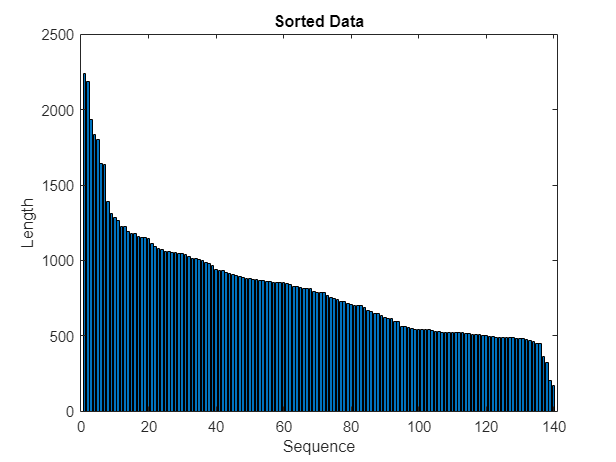

%% Sort data by length of the sequences.

for i=1:numel(X)
    sequence = X{i};
    sequenceLengths(i) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths,'descend');
X = X(idx);
Y = Y(idx);

figure
bar(sequenceLengths)
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

Train contains the first 60% of each battery, Test instead, the remaining 40%.

trainSplit = 0.65;
batt=27;

XTrain = cell(numObservation, 1);
YTrain = cell(numObservation,1);

XTest = cell(numObservation,1);
YTest = cell(numObservation,1);

for i=1:numObservation
    trainSize = round(size(X{i},2)*trainSplit);
    XTrain{i} = X{i}(:,1:trainSize);
    YTrain{i} = Y{i}(:,1:trainSize);

    XTest{i} = X{i}(:,trainSize+1:end);
    YTest{i} = Y{i}(:,trainSize+1:end);
end

Fitting all the curves with Hybrid function, Single (florence paper) and dobule exponential

YTrainSingle = cell(numObservation, 1);
YTrainDouble = cell(numObservation, 1);
YTrainHybrid = cell(numObservation, 1);

% Hybrid model
hybrid_fun = fittype( @(a,b,c,d,x) a+b.*sqrt(x)+c.*(x)+d.*(x.^2));


for i=1:numObservation
    nom_capacity = YTrain{i}(1);

    %Single exp function
    single_exp = fittype( @(a,b,x) nom_capacity + a.*exp(b./x));
    

    YTrainSingle{i} = fit(transpose(XTrain{i}(1,:)), transpose(YTrain{i}), single_exp);
    YTrainDouble{i} = fit(transpose(XTrain{i}(1,:)), transpose(YTrain{i}), 'exp2');
    YTrainHybrid{i} = fit(transpose(XTrain{i}(1,:)), transpose(YTrain{i}), hybrid_fun);
end

Plot the fitting against the true data

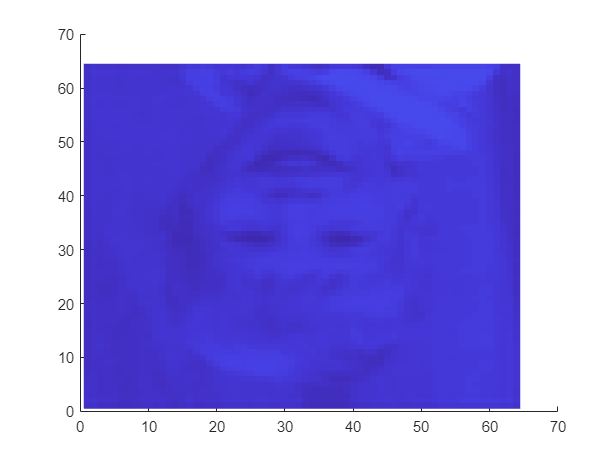

close all
image()

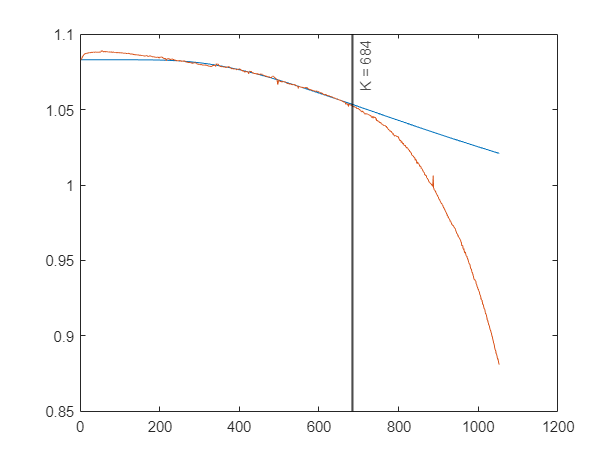

plot(YTrainSingle{batt}(X{batt}(1,:)));
hold on
plot(Y{batt});
predCycle = round(size(X{batt},2)*trainSplit);
xline(predCycle, '-', 'Color','black', 'LineWidth',1.5, 'Label', "K = "+ num2str(predCycle), 'DisplayName', "K = "+ num2str(predCycle));

TRAINING OPTIONS

batt=121;

maxEpochs = 12000; %5500;
miniBatchSize = 1;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'L2Regularization', 0.5,...
    'InitialLearnRate',0.001, ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',2000,...
    'LearnRateDropFactor',0.8,...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'ValidationData', {X{batt}(1,:), Y{batt}}, ...
    'ValidationPatience', 30000, ...
    'ValidationFrequency',100, ...
    'Plots','training-progress',...
    'OutputNetwork','last-iteration',...
    'Verbose',1,...
    'VerboseFrequency',100);



NETWORK


miniBatchSize = 1;
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 100;  % 50 good for k=80. 5 good for k=100  More than 50-100 units add bias to the prediction

%use 30, 25, 15, 12,4,2 or 50
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence', 'InputWeightsL2Factor', 2,'RecurrentWeightsL2Factor',2);
    fullyConnectedLayer(100)
    dropoutLayer(0.5)
    fullyConnectedLayer(numResponses)
    regressionLayer];

%analyzeNetwork(layers)

TRAINING SINGLE EXP

% Use all curve data instead of half of it

predCycle = round(size(X{batt},2)*trainSplit);
x = predCycle/100 : predCycle/100 : predCycle;
x = 1:1:predCycle;
%x = XTrain{batt};  % Prova

y = transpose(YTrainSingle{batt}(x));
%y = YTrain{batt};% Prova

net1 = trainNetwork(x, y ,layers,options);

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |         0.64 |         0.26 |       0.2074 |       0.0349 |          0.0010 |
|     100 |         100 |       00:00:06 |         0.12 |         0.07 |       0.0072 |       0.0022 |          0.0010 |
|     200 |         200 |       00:00:08 |         0.14 |         0.09 |       0.0099 |       0.0044 |          0.0010 |
|     300 |         300 |       00:00:11 |         0.11 |         0.05 |       0.0062 |       0.0012 |          0.0010 |
|     40

%predictions of all curve
YPredFull1 = predict(net1,X{batt}(1,:),'MiniBatchSize',1);
YPred1 = predict(net1,X{batt}(1,predCycle+1:end),'MiniBatchSize',1);
%YPredFull2 = predict(net2,N_cycle,'MiniBatchSize',1);
%YPredFull3 = predict(net3,N_cycle,'MiniBatchSize',1);

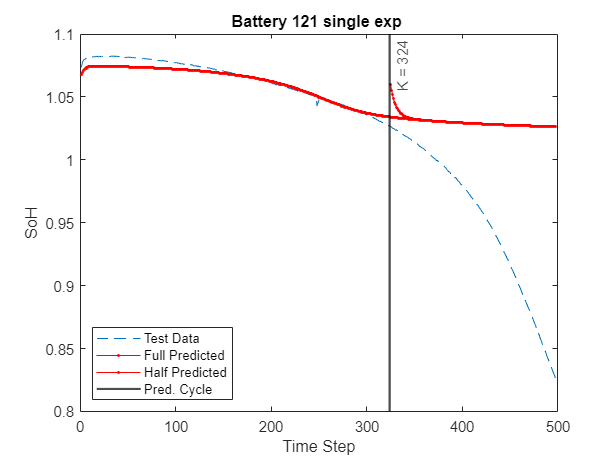

%% Visualize predictions

figure()
plot(X{batt}(1,:),Y{batt},'--')
hold on
%ylim([0.95 1.1])
%plot(XTest{1}, YPred1,'.-')
col=hsv(20);
plot(X{batt}(1,:), YPredFull1, '.-', 'Color',col(1,:))
plot(X{batt}(1,predCycle+1:end), YPred1, '.-', 'Color',col(1,:))
%plot(YTrainSingle{batt}(X{batt}(1,:)));


%plot(N_cycle, YPredFull2, '.-', 'Color',col(2,:))
%plot(N_cycle, YPredFull3, '.-', 'Color',col(3,:))
xline(predCycle, '-', 'Color','black', 'LineWidth',1.5, 'Label', "K = "+ num2str(predCycle), 'DisplayName', "K = "+ num2str(predCycle));
%xline(100, '-', 'Color',col(2,:), 'LineWidth',1.5, 'Label', "K = "+ num2str(100), 'DisplayName', "K = "+ num2str(100));
%xline(120, '-', 'Color',col(3,:), 'LineWidth',1.5, 'Label', "K = "+ num2str(120), 'DisplayName', "K = "+ num2str(120));
hold off
title("Battery " + num2str(batt) + " single exp ")
xlabel("Time Step")
ylabel("SoH")
legend(["Test Data" "Full Predicted" "Half Predicted" "Pred. Cycle"],'Location','southwest')